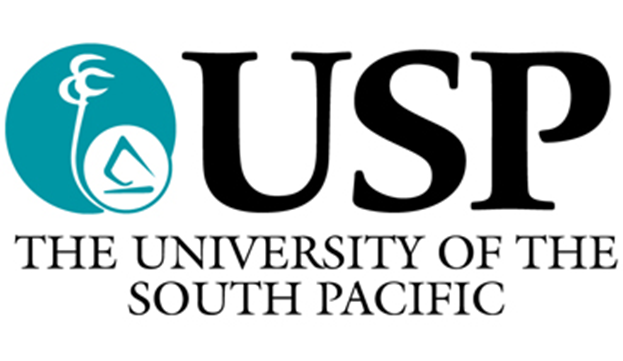

**EE 461: SPECIAL TOPICS IN ELECTRICAL & ELECTRONIC ENGINEETING**

**LAB 1.1: Data Familiarization and Visualization**

**LAB 1.2:  In Depth Data Visualization and Research Component**

**Done by,**

                Avishay Rajeev Narayan (s11199944)

                Pesalili Tohi (s11007076)

                Prateek Gosai (s11197334)

### **INTRODUCTION**

Electricity is one of the most important resources nowadays. One of the core functions of the Electricity Utility Supplier is to make sure, a stable power supply where a minimal disruption time to the electricity supply is maintained [1]. However, the Utility always faced a huge setback with the forever increasing in load demand from their customers [2]. Therefore, to eliminate this problem, load forecasting is very important for the Utility as it will minimise problems arises in the future. Load forecasting used past datasets to predict the future load demand by analysing the trend of the datasets. 

#### CLASSICAL APPROACH

Long Term Load Forecasting is for a period of more than a year to twenty years. All Utility  wanted to do the load forecasting in a minimum of five years. With a minimum of five years load forecasting, Utility will be well informed about what to expect in the next five years. Development of the power supply and delivery system (generation units and distribution system), strategic planning, and the construction of additional generations all depend on this kind of projection [3]. 

Finding and selecting of a model for load forecasting is not an easy task. With numerous models and methods developed for load forecasting, the appropriate ones depend on the load profile trend. There are two categories of electric load forecasting models.

- Multi – factor forecasting method: emphasizes determining the causal connections between various influencing elements and forecasted values [3].

- Time-series forecasting method: depends on historical datasets [3]

### **AIM**

Key purposes of this lab include:

- Data Collection: Obtain historical electrical load data from Tonga (TPL) covering at least the last 5 years.

- Data Preprocessing: Clean and preprocess the data to address any gaps, outliers, and inconsistencies

- Visualize dataset and the behaviour of the system in the data obtained period by plotting different graphs 

### BLOCK DIAGRAM

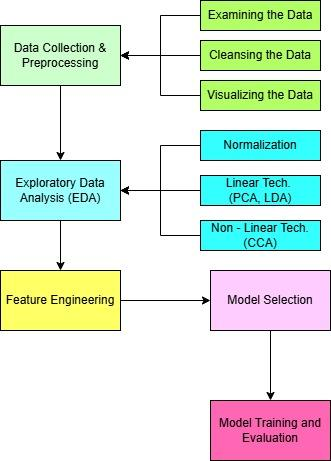

## LAB 1.1: DATA FAMILIARIZATION & VISUALIZTION

### **GENERATION LOCATIONS**

Here are the able indicating locations of Generation Sites in Tongatapu. It consists of Diesel Generations, Solar Farm, Wind Farm and BESS (Battery Energy Storage System).

GSL

GSL = 10×4 table
         GenerationSites           Village      Longitude    Latitiude
    _________________________    ___________    _________    _________

    "Popua Power Station"        "Ánana"         -175.18      -21.159 
    "Maama Mai Solar Farm"       "Ánana"         -175.18      -21.158 
    "Mata ó e Laá Solar Farm"    "Vaini"         -175.19      -21.191 
    "Singyes Solar Farm"         "Tofoa"         -175.23       -21.16 
    "Sunergise 1"                "Fualu"         -175.27      -21.145 
    "Sunergise 2"                "Masilamea"     -175.33      -21.136 
    "Sunergise 3"                "Kolovai"       -175.35      -21.101 
    "I o Manumataongo"           "Niutoua"       -175.04      -21.153 
    "BESS 1"                     "Tofoa"         -175.23      -21.162 
    "Bess 2"                     "Ánana"         -175.18      -21

The above table is the representations of all the power stations located in the main island of Tonga. These stations include theDdiesel Generations, Solar Farms, Wind Farms and Battery Energy Storage Systems. Through this power stations the Tonga Power Limited tracked their records of energy usuage and generations, which provided us with a datasets of nearly 2 decades informations.

### MAPPING

A map of Tongatapu where the locations of Generation sites are being marked.

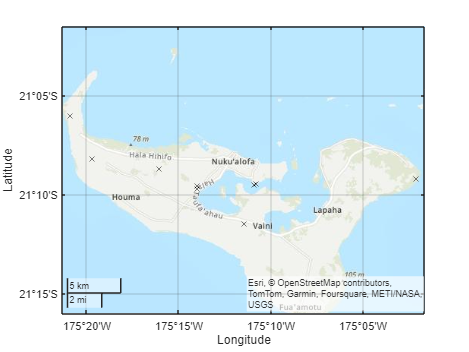

geoscatter(GSL.Latitiude, GSL.Longitude, "xk")
geobasemap topographic

This image is provied to show the pinpoints of the location of the 10 power stations. The imagery was built/made using the inbuilt "geoscatter" command and using 'topographic' as our choice of color trace. The code uses the latitude and the longitude provided from the "GSL" file to map out the accuracy of the location.

### **IMPORT DATASETS**

TPL dataset that was provided to us contains monthly generated power (kW) by Diesel Generators, Solar Farms, Wind Turbines and BESS (Battery Energy Storage System). It also contains amount of power that was send to the distribution network and the total power used by Tonga Power’s Customers in every month. With these datasets information, it is possible to analyse the conditions of the generation system, performance of the distribution network and forecasting loads demand from Customers which classifies as regression based. Amount of diesel used is also features in this dataset which will be very helpful with visualizing the performance of the RE sources in monthly basis. The 2 types of losses also featured in this datasets, which are Parasitic losses and Line losses. Parasitic loss are the power used by Generation facilities . Line loss is the amount of power loss in distribution network.. 

TPL = importfile("ALL_Data.xlsx")

TPL = 222×19 table
       MONTH       GENERATED      SENT_OUT       BILLED      PARASITIC        LINE         TOTAL       PARASITIC_PERCENTAGE    LINE_PERCENTAGE    TOTAL_PERCENTAGE    AVERAGE_PARASITIC_PAST_12_MONTHS    AVERAGE_LINE_PAST_12_MONTHS    AVERAGE_TOTAL_PAST_12_MONTHS    TARGET_PERCENTAGE     FUEL_USE     DIESEL_GEN    RE_GEN    FUEL_EFFICIENCY_DIESEL    FUEL_EFFICIENCY_WITH_RE
    ___________    __________    __________    __________    __________    __________    __________    ____________________    _____________

The table above is the datasets that was collected from TPL. It was than preprocessed using the primary EDA methods. Firstly the data was imported and checked  for any irregularites. The common irregularity founc was the absnce of data for some years, for instance, the "RE_GEN", which is the generation of power using renewable energy sources, was recorded from the month of August in the year 2012. The rest of the previous years was labeled as 'NaN' as it was empty. Using the skills learnt from the practicals, the commands "fillmissing" and "removevars" were used to tidy up the table. 

### HISTOGRAM OF THE DATA "GENERATION"

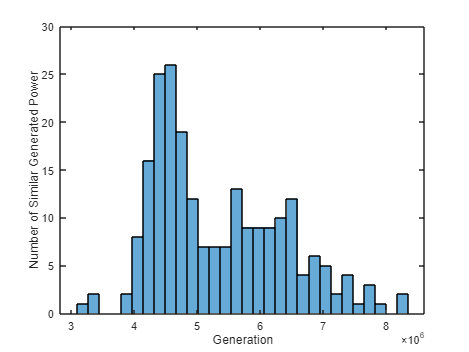

histogram(TPL.GENERATED, 30)
xlabel("Generation")
ylabel("Number of Similar Generated Power")

Using the "histogram" command we were able to generate a graphical representation of the generation of power produced over a monthly basis. Through this we are able to identify patterns, see trends in the production stages and/or anomalies in the data. Through the visualization we can identify facts as such, the production of energy within the range of 4.5 x10^6 kW/H till 4.675 x10^6 kW/H was generated at a count of 26 times.

### HISTOGRAM OF THE DATA "PARASITIC LOSSES"

Parasitic losses is the loss occures before sending the generated power to the customers.

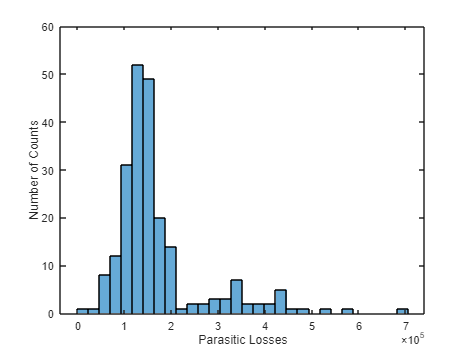

histogram(TPL.PARASITIC, 30)
xlabel("Parasitic Losses")
ylabel("Number of Counts")

This histogram plays a crucial in understanding the behavior of parasitic losses within a generation system. It provides a more clear insight into how these losses are distributed across different time zones (Monthly basis). It helps the engineers and technicians in assessing the system performance and indentifying key ares for improvements.

### HISTOGRAM OF THE DATA "LINE LOSSES"

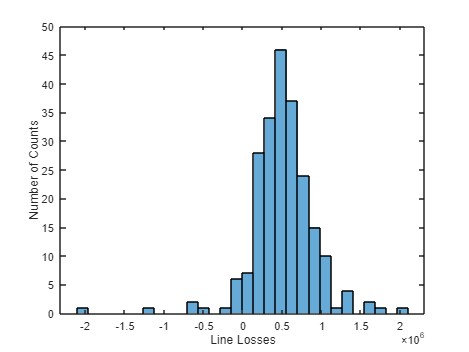

histogram(TPL.LINE, 30)
xlabel("Line Losses")
ylabel("Number of Counts")

### CORRELATION (PARASITIC AND LINE LOSSES)

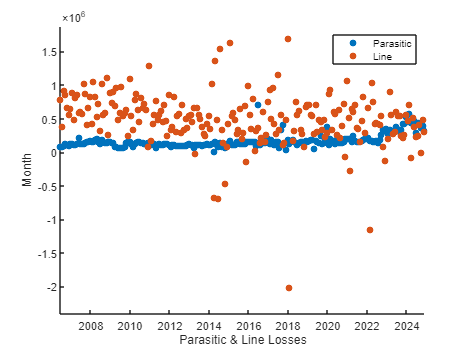

scatter(TPL.MONTH, [TPL.PARASITIC, TPL.LINE], 'filled')
legend("Parasitic","Line")
xlabel("Parasitic & Line Losses")
ylabel("Month")
ylim([-2402556 1877616])

LossesCorrelation = corr(TPL.PARASITIC, TPL.LINE, "rows","complete")

LossesCorrelation = -0.0488

## LAB 1.2: **IN DEPTH DATA VISUALIZATION & RESEARCH COMPONENT**

### SCATTER PLOT OF GENERATION, SEN_OUT  AND BILLED

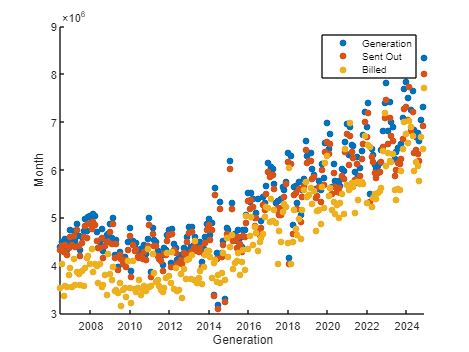

scatter(TPL.MONTH, [TPL.GENERATED, TPL.SENT_OUT, TPL.BILLED], '')
legend("Generation","Sent Out", "Billed")
xlabel('Generation')
ylabel('Month')

LossesCorrelation1 = corr([TPL.GENERATED, TPL.SENT_OUT, TPL.BILLED], "rows","complete")

LossesCorrelation1 =     1.0000    0.9974    0.9187
    0.9974    1.0000    0.9169
    0.9187    0.9169    1.0000


### HISTOGRAM OF THE DATA "GENERATION USING BINWIDTH"

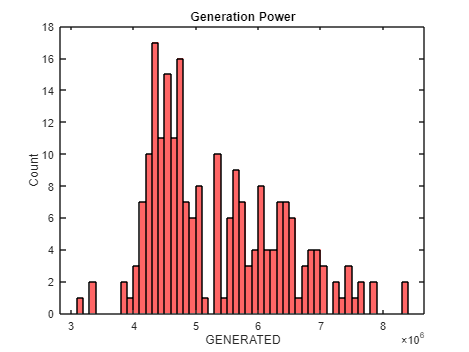

histogram(TPL.GENERATED, "BinWidth", 100000, "FaceColor", "r")
title("Generation Power")
ylabel("Count")
xlabel("GENERATED")

### EXPLORING THE DATASETS (HIGHEST GENERATION)

% Ensure 'TPL' is a table
if ~istable(TPL)
    error('The variable "TPL" must be a table.');
end

% Convert categorical Month to string first, then to datetime
TPL.MonthYear = datetime(string(TPL.MONTH), 'InputFormat', "dd-MMM-uuuu"); 



% Ensure 'GeneratedPower' column exists
if ~any(strcmp("GENERATED", TPL.Properties.VariableNames))
    error('GeneratedPower column is missing from the dataset.');
end

% Group by month and find the maximum generated power
summaryTable = groupsummary(TPL,"MONTH", "max", "GENERATED");

% Find the month with the highest generated power
[~, idx] = max(summaryTable.max_GENERATED);
highestMonth = summaryTable.MONTH(idx);

% Display the result
disp(['The month with the highest generated power is: ', char(highestMonth)]);

The month with the highest generated power is: 01-Dec-2024


### APPLYING PCA

TPL = importfile("ALL_Data.xlsx");
Jul0607 = removevars(TPL,["MONTH"]);
TPL = Jul0607;
tbl = TPL

tbl = 222×18 table
    GENERATED      SENT_OUT       BILLED      PARASITIC        LINE         TOTAL       PARASITIC_PERCENTAGE    LINE_PERCENTAGE    TOTAL_PERCENTAGE    AVERAGE_PARASITIC_PAST_12_MONTHS    AVERAGE_LINE_PAST_12_MONTHS    AVERAGE_TOTAL_PAST_12_MONTHS    TARGET_PERCENTAGE     FUEL_USE     DIESEL_GEN    RE_GEN    FUEL_EFFICIENCY_DIESEL    FUEL_EFFICIENCY_WITH_RE
    __________    __________    __________    __________    __________    __________    ____________________    _______________    ________________    ____

 %Convert to array
X = tbl{:,:};

mu = mean(X); % Row vector of column (feature) means
r = range(X); % Row vector of column ranges
X = (X-mu)./r; % Scaled feature matrix


[P,S,V] = pca(X)

P =    -0.2596    0.1974   -0.1589   -0.0045    0.1183    0.1150   -0.1328   -0.0986   -0.0543   -0.0420    0.0404   -0.2013    0.0019   -0.1532   -0.3155   -0.5486   -0.0822   -0.5798
   -0.2527    0.1814   -0.1966   -0.0408    0.1016    0.1071   -0.2005   -0.0516   -0.0464    0.0136    0.1168   -0.2086    0.0402    0.8372   -0.0852    0.1146    0.0068    0.1258
   -0.2941    0.0437    0.0623   -0.2671    0.2193    0.2516   -0.1887   -0.1047    0.3008   -0.0208    0.0223   -0.1599   -0.0299   -0.3731   -0.4369    0.3055   -0.0298    0.3691
   -0.1367    0.1801    0.2135    0.2563    0.1586    0.0952    0.4356   -0.3666   -0.0747   -0.4084   -0.5285   -0.0157    0.0060    0.0883   -0.0428   -0.0467    0.0259    0.1215
    0.0243    0.1688   -0.3048    0.2481   -0.1222   -0.1515   -0.0305    0.0546   -0.3899    0.0394    0.1152   -0.0721    0.0019   -0.1759   -0.1822   -0.3725    0.1476    0.6148
    0.0012    0.1970   -0.2658    0.2882   -0.0944   -0.1340    0.0426   -0.0072   -0.3983 

S =     0.8690    0.3158   -0.0004   -0.1713   -0.0460   -0.2086   -0.0415   -0.0284    0.0051   -0.0018   -0.0121   -0.0034   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.8061    0.1927    0.0816   -0.2134   -0.0142    0.0979   -0.0731    0.0013   -0.0143   -0.0080   -0.0072    0.0008    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.8826    0.3399   -0.0303   -0.0988   -0.0747   -0.2162   -0.0082   -0.0343    0.0121   -0.0020   -0.0084   -0.0035    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.8269    0.3623   -0.0286   -0.1046   -0.0256   -0.1420    0.0066   -0.0628    0.0037    0.0071   -0.0051   -0.0017    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.8713    0.2413    0.0470   -0.0742   -0.0869   -0.0097    0.0159   -0.0221    0.0031   -0.0087    0.0012   -0.0011   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.8279    0.2445    0.0465   -0.1624   -0.0333    0.0062   -0.0390   -0.0172   -0.0062 

V =     0.5214
    0.1004
    0.0456
    0.0290
    0.0194
    0.0151
    0.0101
    0.0091
    0.0005
    0.0002


[coeff, score, latent, tsquared, explained, mu] = pca(X)

coeff =    -0.2596    0.1974   -0.1589   -0.0045    0.1183    0.1150   -0.1328   -0.0986   -0.0543   -0.0420    0.0404   -0.2013    0.0019   -0.1532   -0.3155   -0.5486   -0.0822   -0.5798
   -0.2527    0.1814   -0.1966   -0.0408    0.1016    0.1071   -0.2005   -0.0516   -0.0464    0.0136    0.1168   -0.2086    0.0402    0.8372   -0.0852    0.1146    0.0068    0.1258
   -0.2941    0.0437    0.0623   -0.2671    0.2193    0.2516   -0.1887   -0.1047    0.3008   -0.0208    0.0223   -0.1599   -0.0299   -0.3731   -0.4369    0.3055   -0.0298    0.3691
   -0.1367    0.1801    0.2135    0.2563    0.1586    0.0952    0.4356   -0.3666   -0.0747   -0.4084   -0.5285   -0.0157    0.0060    0.0883   -0.0428   -0.0467    0.0259    0.1215
    0.0243    0.1688   -0.3048    0.2481   -0.1222   -0.1515   -0.0305    0.0546   -0.3899    0.0394    0.1152   -0.0721    0.0019   -0.1759   -0.1822   -0.3725    0.1476    0.6148
    0.0012    0.1970   -0.2658    0.2882   -0.0944   -0.1340    0.0426   -0.0072   -0.3

score =     0.8690    0.3158   -0.0004   -0.1713   -0.0460   -0.2086   -0.0415   -0.0284    0.0051   -0.0018   -0.0121   -0.0034   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.8061    0.1927    0.0816   -0.2134   -0.0142    0.0979   -0.0731    0.0013   -0.0143   -0.0080   -0.0072    0.0008    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.8826    0.3399   -0.0303   -0.0988   -0.0747   -0.2162   -0.0082   -0.0343    0.0121   -0.0020   -0.0084   -0.0035    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.8269    0.3623   -0.0286   -0.1046   -0.0256   -0.1420    0.0066   -0.0628    0.0037    0.0071   -0.0051   -0.0017    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.8713    0.2413    0.0470   -0.0742   -0.0869   -0.0097    0.0159   -0.0221    0.0031   -0.0087    0.0012   -0.0011   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.8279    0.2445    0.0465   -0.1624   -0.0333    0.0062   -0.0390   -0.0172   -0.0

latent =     0.5214
    0.1004
    0.0456
    0.0290
    0.0194
    0.0151
    0.0101
    0.0091
    0.0005
    0.0002


tsquared =    10.1018
    6.1198
    9.0744
    5.7339
    3.2462
    3.8516
    3.8317
    3.1776
    7.7122
    2.9098


explained =    69.4443
   13.3704
    6.0692
    3.8644
    2.5841
    2.0166
    1.3395
    1.2105
    0.0623
    0.0287


mu = 1.0e-14 *

   -0.0028   -0.0341   -0.0067   -0.0007   -0.0002   -0.0023    0.0022   -0.0009    0.0021   -0.0043   -0.0011   -0.0107    0.1892    0.0022    0.0082   -0.0004    0.0233    0.0163


#### PARETO CHART

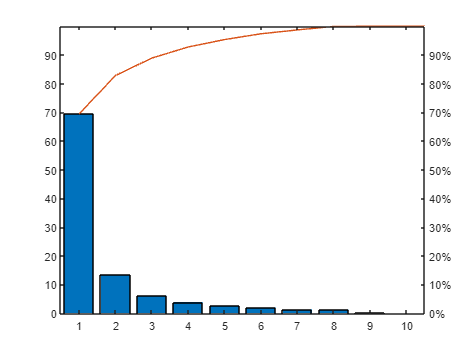

close all;
figure;
pareto(explained,1)

#### NORMALIZE

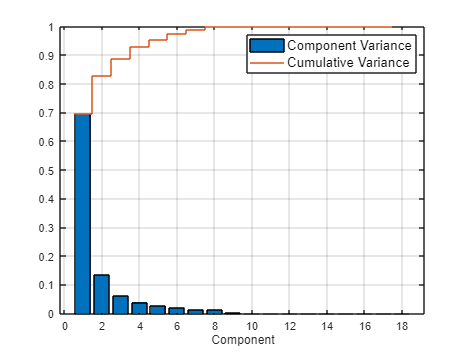

% Examine the principle component variances
Vnorm = V/sum(V); % Normalize the variance so the total is 1
figure; hold on;
bar(Vnorm);
stairs(0.5:17.5,cumsum(Vnorm));
grid on; box on; hold off;
set(gca,'XTick',0:2:18)
legend({'Component Variance','Cumulative Variance'},'FontSize',12)
xlabel('Component')

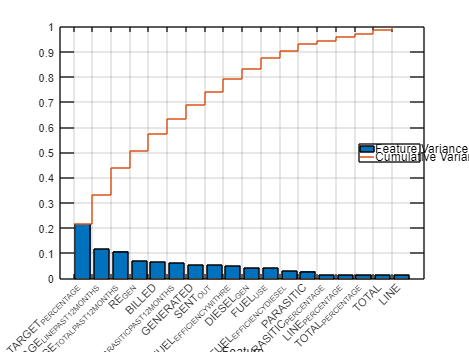

% Examine the original feature variances
VOrigNorm = var(X);
[VOrigNorm,idx] = sort(VOrigNorm,'descend');
VOrigNorm = VOrigNorm/sum(VOrigNorm); % Normalize the variance so the total is 1
figure; hold on;
bar(VOrigNorm);
stairs(0.5:17.5,cumsum(VOrigNorm));
grid on; box on; hold off;
set(gca,'XTick',0.5:17.5,'XTickLabel',tbl.Properties.VariableNames(idx),'XTickLabelRotation',45)
set(gcf,'units','normalized','OuterPosition',[0 0 1 1])
legend({'Feature Variance','Cumulative Variance'},'FontSize',11,'Location','east')
xlabel('Feature')
ylim([0,1])

## REMARKS

## REFERENCE

[1] 	Z. N. Md. Rashedul Haq, "A New Hybrid Model for Short-Term Electricity Load Forecasting," vol. 7, pp. 125413-125423, 2019. 
[2] 	Z. M. &. B. N. J. Nicolai Bo Vanting, "A scoping review of deep neural networks for electric load forecasting," Energy Inform 4 (Suppl 2), vol. 4, no. 49, 2021. 
[3] 	B. J. B. R. D. D. Mahmoud A. HAMMAD, "Methods and Models for Electric Load Forecasting: A Comprehensive Review," Logistics & Sustainable Transport , vol. 11, no. 1, pp. 51 - 76, 2020. 
